# レーティング変換の例

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む

load sample_ratingConv.mat

レーティング最小値と最大値の確認

[min(RateDiff) max(RateDiff)]

ans =   -18.3681   18.9566


実際の勝敗ごとにレーティングを集計

edges=-20:20;
bins=movmean(edges,2,'Endpoints','discard');
winCounts=histcounts( RateDiff(ActualWin==1),edges);
loseCounts=histcounts( RateDiff(ActualWin==0),edges);

figure
subplot(2,1,1)
bar(bins,[winCounts;loseCounts],'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','メイリオ','FontSize',12)
ylabel('試合数')
set(gca,'XTickLabel',[])
legend({'勝ち','負け'},'location','best')

subplot(2,1,2)
set(gca,'FontName','メイリオ','FontSize',12)
bar(bins,[winCounts;loseCounts]./(winCounts+loseCounts), ...
    'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','arial','FontSize',12)
ylabel('割合')
xlabel('レーティング差(ホーム-アウェー)')

レーティング差と勝率の対応をロジスティック回帰として求める

mdl=glmfit(RateDiff, ActualWin,'binomial','logit')

mdl =     0.3948
    0.1189


glmval(mdl,0,'logit')

ans = 0.5974

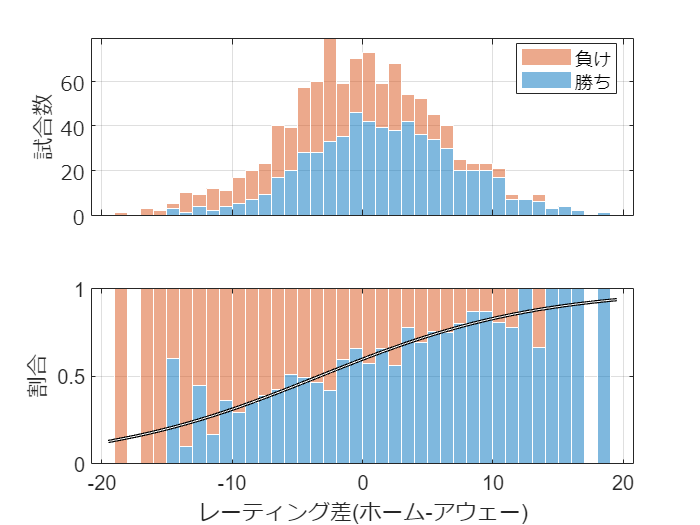

subplot(2,1,2)
hold on
plot(bins, glmval(mdl,bins,'logit'),'k-','LineWidth',2);
y=1./(1+exp(-mdl(1)-mdl(2)*bins));
plot(bins,y,'w-')

exportgraphics(gcf,'fig_ratingTransformationExample.pdf');

### 1試合に対しそれぞれのチームから見た結果と予測に基づきモデルを導出する

レーティング差と実勝敗それぞれ対戦相手から見た値を追加する．

RateDiff_org=RateDiff;
RateDiff=[RateDiff_org;-RateDiff_org];

ActualWin_org=ActualWin;
ActualWin=[ActualWin_org;1-ActualWin_org];

これ以降の処理は前半と全く同じ．実際の勝敗ごとにレーティングを集計

edges=-20:20;
bins=movmean(edges,2,'Endpoints','discard');
winCounts=histcounts( RateDiff(ActualWin==1),edges);
loseCounts=histcounts( RateDiff(ActualWin==0),edges);

figure
subplot(2,1,1)
bar(bins,[winCounts;loseCounts],'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','メイリオ','FontSize',12)
ylabel('試合数')
set(gca,'XTickLabel',[])
legend({'勝ち','負け'},'location','best')

subplot(2,1,2)
set(gca,'FontName','メイリオ','FontSize',12)
bar(bins,[winCounts;loseCounts]./(winCounts+loseCounts), ...
    'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','arial','FontSize',12)
ylabel('割合')
xlabel('レーティング差')

レーティング差と勝率の対応をロジスティック回帰として求める

mdl=glmfit(RateDiff, ActualWin,'binomial','logit')

mdl =    -0.0000
    0.1156


glmval(mdl,0,'logit')

ans = 0.5000

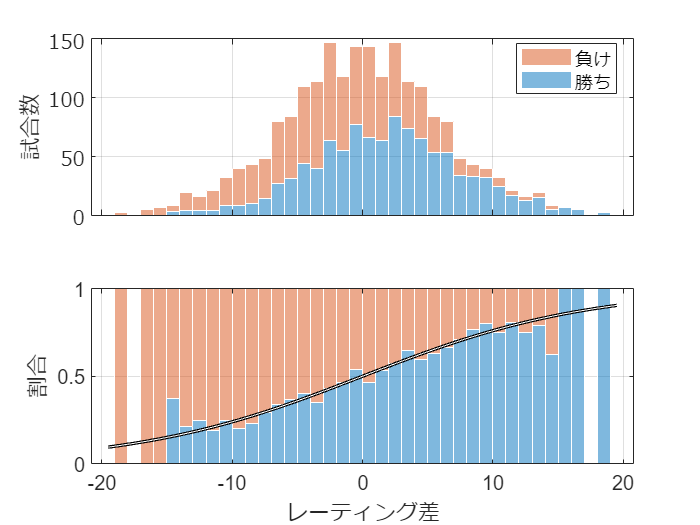

subplot(2,1,2)
hold on
plot(bins, glmval(mdl,bins,'logit'),'k-','LineWidth',2);
y=1./(1+exp(-mdl(1)-mdl(2)*bins));
plot(bins,y,'w-')

exportgraphics(gcf,'fig_ratingTransformationExample02.pdf');